%run thesis_aggregated_eval.mlx

pathfig = 'C:\Users\u0130154\MATLAB\projects\seasize\thesis_figure';
pathpng = 'C:\Users\u0130154\OneDrive - KU Leuven\PhD\_writing\_thesis\phdthesis\chapters\actuatordesign\image';

motname = '';

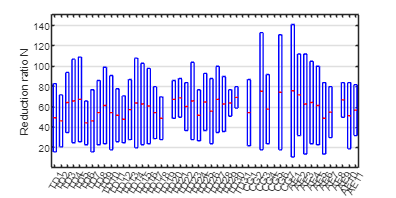


%% Plot a boxplot of the feasible gearbox ratios
[feasresults, feasfig]=gearevals.feasableBoxplot(pat);
fig=figure(feasfig);
hold on
yline(81, 'r', LineWidth=1.5)
% Get handle to the current axes
ax = gca;
% Rotate x-axis labels by 45 degrees
set(ax, 'XTickLabelRotation', 60);
set(ax, 'FontSize', 7);

fig.Units = 'inches';
fig.Position = [0, 0, 6, 3];
title('')
% Save the figure as PNG
savefig([pathfig '\aggrfeas' motname])
export_fig([pathpng '\aggrfeas' motname '.png' ], '-png', '-r300', '-nocrop', '-transparent')

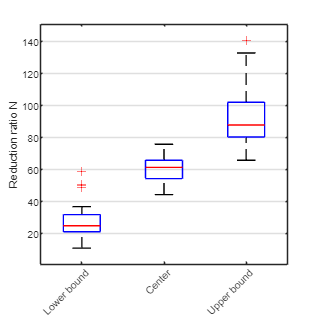


feasboundsfig=gearevals.feasableBoxplotBounds;
hold on
yline(81, 'r', LineWidth=1.5)
hold off
ax = gca;
% Rotate x-axis labels by 45 degrees
set(ax, 'XTickLabelRotation', 45);
set(ax, 'FontSize', 7);

feasboundsfig.Units = 'inches';
feasboundsfig.Position = [0, 0, 3, 3];
title('')
% Save the figure as PNG
savefig([pathfig '\aggrfeasbounds' motname])
export_fig([pathpng '\aggrfeasbounds' motname '.png' ], '-png', '-r300', '-nocrop', '-transparent')

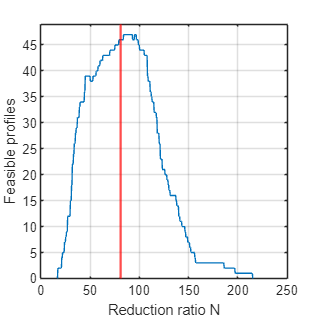

feasboundsfig=gearevals.feasableStaircase(500);
hold on
xline(81, 'r', LineWidth=1.5)
hold off
ax = gca;
grid on
feasboundsfig.Units = 'inches';
feasboundsfig.Position = [0, 0, 4, 2.5];
title('')
% Save the figure as PNG
savefig([pathfig '\aggrfeasstair' motname])
export_fig([pathpng '\aggrfeasstair' motname '.png' ], '-png', '-r300', '-nocrop', '-transparent')

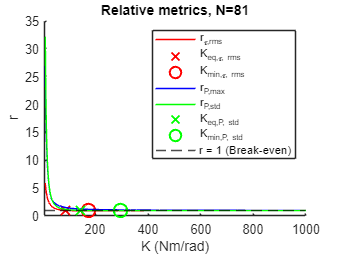

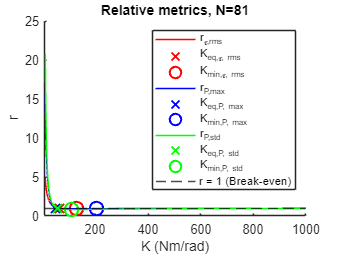

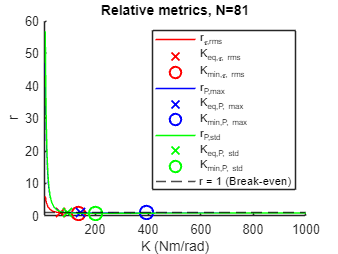

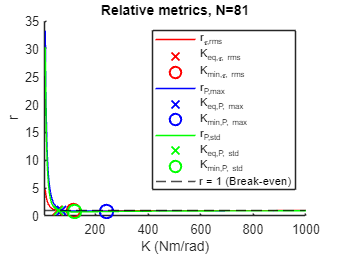

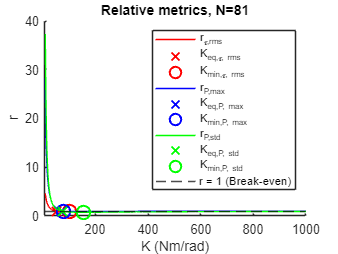

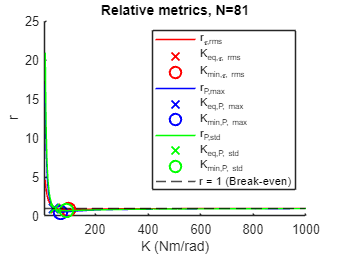

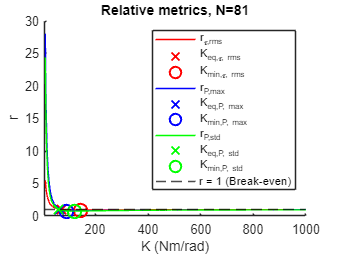

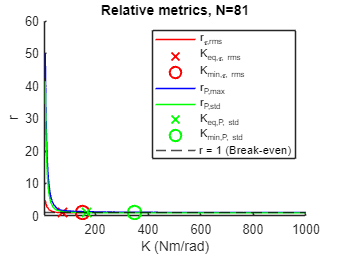


clear results_sel figsel
for i = 1:nr
    clear temp_result temp_fig
    [temp_result, temp_fig]=gearevals(i).plotSelected('N', 81, 'K', [10 1000 1000]);
    results_sel{i} =temp_result;
    figsel{i} = temp_fig;
end

for i = 1:nr
    clear temp_result
    temp_result = results_sel{i};
    Keqtrm(i) = temp_result.K_be_rms_tor;
    Kmintrms(i) = temp_result.K_min_rms_tor;
    KeqPpk(i) = temp_result.K_be_pk_p;
    KminPpk(i) = temp_result.K_min_pk_p;
    KeqPstd(i) = temp_result.K_be_std_p;
    KminPstd(i) = temp_result.K_min_std_p;
end
boxplot([Keqtrm;Kmintrms;KeqPpk;KminPpk;KeqPstd;KminPstd]', Labels={'$$K_{eq,\tau rms}$$', '$$K_{min,\tau rms}$$', '$$K_{eq,P\,max}$$', '$$K_{min,P\,max}$$', '$$K_{eq,P\,std}$$', '$$K_{min,P\,std}$$'});
ylabel('$K$\,(Nm/rad)', "Interpreter","latex");
ax=gca

ax =   Axes with properties:

             XLim: [0.5000 6.5000]
             YLim: [-9.3243 1.0481e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1929 0.7750 0.7321]
            Units: 'normalized'

  Show all properties


ax.TickLabelInterpreter= 'latex';
grid on
fig=gcf

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


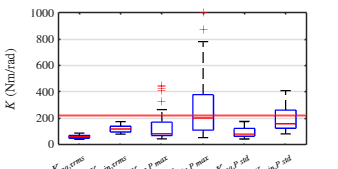

fig.Units = 'inches';
fig.Position = [0, 0, 3, 3];
title('')
ylim([0 1000]);
yline(220, 'r', LineWidth=1.5);
hold off
set(gca,'XGrid','off','YGrid','on');
% Save the figure as PNG
savefig([pathfig '\aggrstiff' ])
export_fig([pathpng '\aggrstiff.png' ], '-png', '-r300', '-nocrop', '-transparent')


Kstats=table(meanstdminmaxCV(Keqtrm)',...
    meanstdminmaxCV(Kmintrms)', ...
    meanstdminmaxCV(KeqPpk)', ...
    meanstdminmaxCV(KminPpk)', ...
    meanstdminmaxCV(KeqPstd)', ...
    meanstdminmaxCV(KminPstd)')

Kstats = 9×6 table
      Var1        Var2       Var3      Var4      Var5       Var6  
    ________    ________    ______    ______    _______    _______

      38.739      77.387    41.712    51.622     40.721     79.369
      57.568      117.03    81.847    200.77     77.883     156.67
      58.498      118.06     142.4     312.2     90.828     191.58
      85.315      172.52    449.01      1000     173.51     408.38
      21.802      44.099    102.57    270.05     59.955     138.24
      13.282      26.617    120.64    294.71     38.784      85.87
      2.2023      2.2293    10.765    19.372     4.2611     5.1453
    0.062077    0.072484    1.4886    1.4399    0.70417    0.73861
          49          49        40        40         48         48


printlatextable(Kstats)